% формирование массива данных из листов с ГИС и суммы ГРС для аппроксимации запаса
d = dir('C:\Users\user\MATLAB Drive\1Exponenta\27.02_zapas\data_all\Запас данные');
d(1:3) = []; %создание пустого массива
t1 = [];

for i = 1:numel(d)
    disp(i)% демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; %считываем имя файла в директории d
    [a,txt] = readfile_all(str); % читаем файл, к которому обращаемся
    b = txt(6:end,2);
    B = ismissing(b);
    b(B) = [];
    c = categorical(b);
    b1 = double(c);
    t1 = [t1; [b1, a(:,1:23)]];
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



t2 = t1;
t2(1,:)= [];

for j = 1 :length(t1)
   t2([j+2],:) = [];
end

Matrix index is out of range for deletion.

t2(1,1)= [12];
t2(end,:)= [];

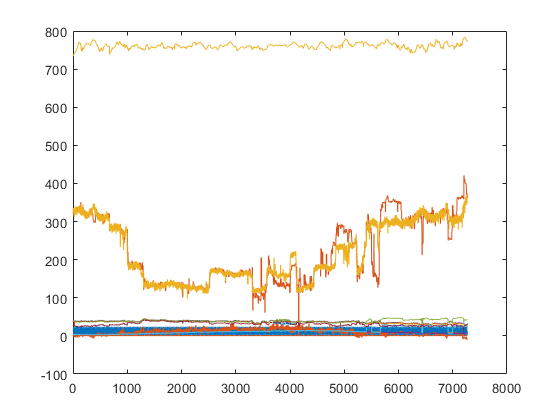

plot(t1);

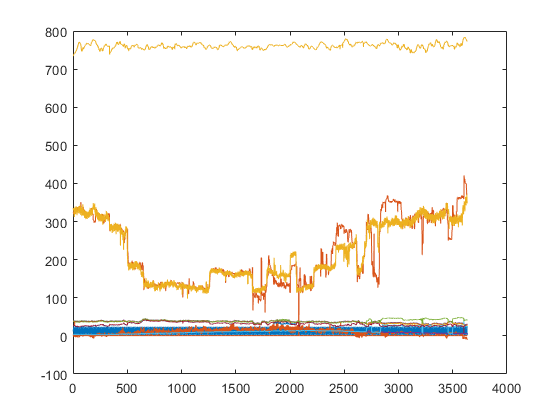

plot(t2);

% plot(t);

Unrecognized function or variable 't'.

save zapas_temper t2

function [t1,txt] = readfile_all(str)
[t1,txt] = xlsread(str,'КС, МГ');
s = all(isnan(t1));
t1(:,s) = [];
b = all(isnan(t1),2);
t1(b,:) = [];
end